% EET3422 Lab 2: Waveguide with Basic 3D Plotting
clear; close all; clc;

%% Define Geometric Parameters
waveguide_length = 10.16e-3;
waveguide_width = 22.86e-3;
waveguide_height = 31e-3;

fprintf('Waveguide dimensions:\n');

Waveguide dimensions:


fprintf('Length: %.1fmm, Width: %.1fmm, Height: %.1fmm\n', ...
    waveguide_length*1000, waveguide_width*1000, waveguide_height*1000);

Length: 10.2mm, Width: 22.9mm, Height: 31.0mm



%% Create Waveguide using Basic 3D Plotting
fprintf('\nCreating waveguide using 3D plotting...\n');


Creating waveguide using 3D plotting...


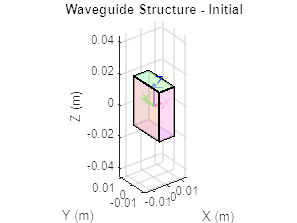


L = waveguide_length;
W = waveguide_width; 
H = waveguide_height;

% Create figure for initial waveguide
figure('Name', 'Waveguide - Initial', 'Position', [100, 100, 800, 600]);
hold on;

% Define the 8 vertices of the waveguide
vertices = [
    -L/2, -W/2, -H/2;  % 1
    -L/2,  W/2, -H/2;  % 2
     L/2,  W/2, -H/2;  % 3
     L/2, -W/2, -H/2;  % 4
    -L/2, -W/2,  H/2;  % 5
    -L/2,  W/2,  H/2;  % 6
     L/2,  W/2,  H/2;  % 7
     L/2, -W/2,  H/2;  % 8
];

% Define the 6 faces (each face has 4 vertices)
faces = {
    [1, 2, 3, 4],  % Bottom face
    [5, 6, 7, 8],  % Top face
    [1, 2, 6, 5],  % Side face 1
    [2, 3, 7, 6],  % Side face 2  
    [3, 4, 8, 7],  % Side face 3
    [4, 1, 5, 8]   % Side face 4
};

% Colors for different faces
colors = [
    0.8 0.8 1.0;  % Light blue - bottom
    0.8 1.0 0.8;  % Light green - top
    1.0 0.8 0.8;  % Light red - side 1
    0.8 1.0 1.0;  % Light cyan - side 2
    1.0 1.0 0.8;  % Light yellow - side 3
    1.0 0.8 1.0;  % Light magenta - side 4
];

% Plot each face
for i = 1:length(faces)
    face_vertices = vertices(faces{i}, :);
    patch(face_vertices(:,1), face_vertices(:,2), face_vertices(:,3), ...
          colors(i,:), 'FaceAlpha', 0.7, 'EdgeColor', 'k', 'LineWidth', 1.5);
end

% Add labels and formatting
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Waveguide Structure - Initial');
grid on;
axis equal;
view(3); % 3D view
rotate3d on; % Enable rotation

% Add coordinate system
quiver3(0, 0, 0, L/2, 0, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, 0, 0, W/2, 0, 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, 0, 0, 0, H/2, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5);
text(L/2, 0, 0, 'X', 'Color', 'r', 'FontSize', 12);
text(0, W/2, 0, 'Y', 'Color', 'g', 'FontSize', 12);
text(0, 0, H/2, 'Z', 'Color', 'b', 'FontSize', 12);

hold off;

fprintf('Initial waveguide created successfully.\n');

Initial waveguide created successfully.



%% Rotate Waveguide 90 degrees around Y-axis
fprintf('\nRotating waveguide 90 degrees around Y-axis...\n');


Rotating waveguide 90 degrees around Y-axis...


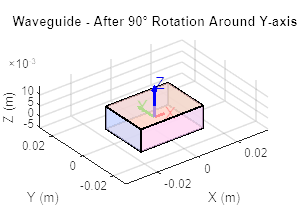


figure('Name', 'Waveguide - Rotated', 'Position', [100, 100, 800, 600]);
hold on;

% Rotation matrix for 90 degrees around Y-axis
theta = pi/2; % 90 degrees
R = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];

% Apply rotation to vertices
rotated_vertices = (R * vertices')';

% Plot each face of rotated waveguide
for i = 1:length(faces)
    face_vertices = rotated_vertices(faces{i}, :);
    patch(face_vertices(:,1), face_vertices(:,2), face_vertices(:,3), ...
          colors(i,:), 'FaceAlpha', 0.7, 'EdgeColor', 'k', 'LineWidth', 1.5);
end

xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Waveguide - After 90° Rotation Around Y-axis');
grid on;
axis equal;
view(3);
rotate3d on;

% Add coordinate system
quiver3(0, 0, 0, L/2, 0, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, 0, 0, W/2, 0, 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, 0, 0, 0, H/2, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5);
text(L/2, 0, 0, 'X', 'Color', 'r', 'FontSize', 12);
text(0, W/2, 0, 'Y', 'Color', 'g', 'FontSize', 12);
text(0, 0, H/2, 'Z', 'Color', 'b', 'FontSize', 12);

hold off;

fprintf('Waveguide rotated successfully.\n');

Waveguide rotated successfully.



%% Translate Waveguide
fprintf('\nTranslating waveguide by [0, 0, %.4f]...\n', L/2);


Translating waveguide by [0, 0, 0.0051]...


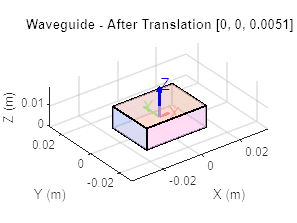


figure('Name', 'Waveguide - Translated', 'Position', [100, 100, 800, 600]);
hold on;

% Apply translation: [0, 0, L/2]
translation = [0, 0, L/2];
translated_vertices = rotated_vertices + translation;

% Plot each face of translated waveguide
for i = 1:length(faces)
    face_vertices = translated_vertices(faces{i}, :);
    patch(face_vertices(:,1), face_vertices(:,2), face_vertices(:,3), ...
          colors(i,:), 'FaceAlpha', 0.7, 'EdgeColor', 'k', 'LineWidth', 1.5);
end

xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title(sprintf('Waveguide - After Translation [0, 0, %.4f]', L/2));
grid on;
axis equal;
view(3);
rotate3d on;

% Add coordinate system
quiver3(0, 0, L/2, L/2, 0, 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, L/2, 0, W/2, 0, 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, L/2, 0, 0, H/2, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5);
text(L/2, 0, L/2, 'X', 'Color', 'r', 'FontSize', 12);
text(0, W/2, L/2, 'Y', 'Color', 'g', 'FontSize', 12);
text(0, 0, L/2 + H/2, 'Z', 'Color', 'b', 'FontSize', 12);

hold off;

fprintf('Waveguide translated successfully.\n');

Waveguide translated successfully.


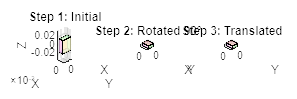


%% Create Comparison Figure
figure('Name', 'Waveguide - All Steps', 'Position', [100, 100, 1200, 400]);

% Subplot 1: Initial
subplot(1,3,1);
hold on;
for i = 1:length(faces)
    face_vertices = vertices(faces{i}, :);
    patch(face_vertices(:,1), face_vertices(:,2), face_vertices(:,3), ...
          colors(i,:), 'FaceAlpha', 0.7, 'EdgeColor', 'k', 'LineWidth', 1);
end
title('Step 1: Initial');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal; view(45,30);
hold off;

% Subplot 2: Rotated
subplot(1,3,2);
hold on;
for i = 1:length(faces)
    face_vertices = rotated_vertices(faces{i}, :);
    patch(face_vertices(:,1), face_vertices(:,2), face_vertices(:,3), ...
          colors(i,:), 'FaceAlpha', 0.7, 'EdgeColor', 'k', 'LineWidth', 1);
end
title('Step 2: Rotated 90°');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal; view(45,30);
hold off;

% Subplot 3: Translated
subplot(1,3,3);
hold on;
for i = 1:length(faces)
    face_vertices = translated_vertices(faces{i}, :);
    patch(face_vertices(:,1), face_vertices(:,2), face_vertices(:,3), ...
          colors(i,:), 'FaceAlpha', 0.7, 'EdgeColor', 'k', 'LineWidth', 1);
end
title('Step 3: Translated');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal; view(45,30);
hold off;


%% Summary
fprintf('\n=== WAVEGUIDE 3D VISUALIZATION COMPLETE ===\n');


=== WAVEGUIDE 3D VISUALIZATION COMPLETE ===


fprintf('Generated 4 figures:\n');

Generated 4 figures:


fprintf('1. Waveguide - Initial: Basic waveguide\n');

1. Waveguide - Initial: Basic waveguide


fprintf('2. Waveguide - Rotated: After 90° rotation\n');

2. Waveguide - Rotated: After 90° rotation


fprintf('3. Waveguide - Translated: After translation\n');

3. Waveguide - Translated: After translation


fprintf('4. Waveguide - All Steps: Comparison of all steps\n');

4. Waveguide - All Steps: Comparison of all steps


fprintf('\nYou can rotate any 3D figure by clicking and dragging.\n');


You can rotate any 3D figure by clicking and dragging.


fprintf('Each face is colored differently for better visualization.\n');

Each face is colored differently for better visualization.
